**3. (10 marks) The input to a Wiener filter of length two is described by the difference equation, u(n) = x(n) +  v2(n), where x(n) = 0.56x(n-1) + 0.32 x(n-2) + v1(n), and v1(n) and v2(n) are zero-mean white noise processes  of variances 0.5 and 0.2 respectively. The desired input is given by the difference equation, d(n) = 0.65 x(n)  + 0.94 x(n-1). Derive the equations for the error performance surface and the Wiener filter for this example.  Do the following in MATLAB (see “WienerExample.mlx” for guidance):**

**a. Plot the error performance surface as function of the weights.**

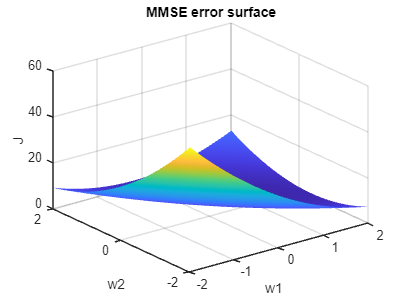

% Parameters
N = 1000; % Number of samples
var_v1 = 0.5;
var_v2 = 0.2;

% Generate white noise
v1 = sqrt(var_v1)*randn(1, N);
v2 = sqrt(var_v2)*randn(1, N);

% Preallocate x and u
x = zeros(1, N);
u = zeros(1, N);

% Generate x(n) and u(n)
for n = 3:N
    x(n) = 0.56*x(n-1) + 0.32*x(n-2) + v1(n);
    u(n) = x(n) + v2(n);
end

d = 0.65*x(2:N) + 0.94*x(1:N-1);

% Calculation of autocorrelation matrix R and cross-correlation vector P
R = zeros(2,2);
P = zeros(2,1);
for n = 3:N 
    R = R + [u(n)*conj(u(n)), u(n)*conj(u(n-1)); u(n-1)*conj(u(n)), u(n-1)*conj(u(n-1))]/(N-2); %use average of the instantaneous value 
    P = P + [u(n); u(n-1)]*conj(d(n))/(N-2); %use average of the instantaneous value 
end

% Calculate J(w)
w1 = -2:0.05:2;
w2 = -2:0.05:2;
J = zeros(length(w1), length(w2));
for i = 1:length(w1)
    for j = 1:length(w2)
        w = [w1(i); w2(j)];
        J(i,j) =var(d) - P'*w - w'*P + w'*R*w ; %J(w) = (variance of the desired output) - (P^(H) )* W - (W^(H)) * P + W^(H) * R * W
    end
end

% Plotting
figure(1)
surf(w1,w2,J,'EdgeColor','None')
xlabel('w1');ylabel('w2');zlabel('J');title('MMSE error surface');

**b. Plot the contours of the error performance surface and indicate the Wiener solution on this plot. **

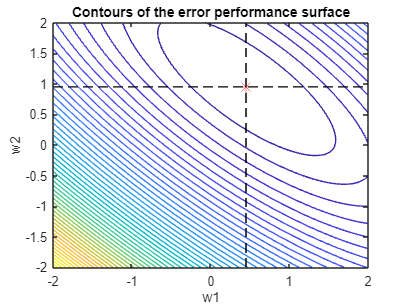

figure(2)
contour(w1, w2, J', 50); 
xlabel('w1'); 
ylabel('w2'); 
title('Contours of the error performance surface');
[MinError, MinIndex] = min(J(:)); % Find the minimum error point
[i, j] = ind2sub(size(J), MinIndex); % Convert the linear index to subscripts to find the indices for w1 and w2
WS1= w1(i); % Get the corresponding coordination
WS2 = w2(j);
hold on; 
plot(WS1, WS2, 'r*', 'MarkerSize', 10); % Indicate the Wiener solution
line([WS1 WS1], ylim, 'Color', 'black', 'LineStyle', '--'); 
line(xlim, [WS2 WS2], 'Color', 'black', 'LineStyle', '--'); 
hold off; 

**c. Plot the gradient vectors and comment on their orientation.**

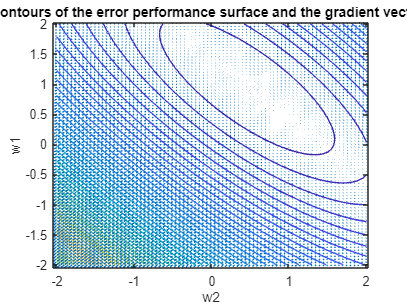

[u,v]=gradient(J,0.5);
figure(3)
contour(w1, w2, J', 50);
xlabel('w2');ylabel('w1');title('Contours of the error performance surface and the gradient vectors');
hold on;
quiver(w1,w2,u,v)
hold off;